# An illustration of 2 different identification schemes

In this note, I illustrate two prominent identification schemes and how they can be implemented in Matlab. 

We start with a known, simulated model, so we can be sure of how the techniques change the results. To illustrate the Cholesky decomposition visually clearly it will be worthwhile to assume a non-diagonal covariance matrix (i.e. correlated shocks).

Set up the simulated data:


A0 = [0; 0]
A1 = [0.6 -0.2; 0.2 0.6]
Trend = [0; 0] 
Sigma = eye(2)+0.4; % eye(2) gives a 2x2 identity matrix; What does the sumation do to the eye matrix?
Mdl_True = varm('Constant',A0,'AR',{A1},'Trend',Trend,...
    'Covariance',Sigma)
rng(1) % for reproducibility 
T = 100;
Y = simulate(Mdl_True,T);

Specify the VAR model to be estimated: 

num_variables = 2;
num_lags = 1;
Mdl_VAR = varm(num_variables,num_lags)

Estimate the VAR:

Est_Mdl_VAR = estimate(Mdl_VAR,Y)
summarize(Est_Mdl_VAR)
Results_Mdl_VAR = summarize(Est_Mdl_VAR)

Compute its generalized IRF, where we allow arbitrary correlation across the residuals:

irf_periods=30;
[IRF_VAR,IRF_VAR_lower,IRF_VAR_upper] = irf(Est_Mdl_VAR,"Method","generalized","NumObs",irf_periods);

I wrote the function below to generate neat graphs in a matrix of panels. It reads all dimensions from the size of the 3D IRF input [irf periods x number of shocks x number of variables ]

irf_plot(IRF_VAR,IRF_VAR_lower,IRF_VAR_upper)

## Cholesky decomposition

The estimates above are of the *reduced form *(using the notation in the lecture):


$$\mathbf{y}_t=A_0 +A_1\mathbf{y}_{t-1}+\mathbf{e}_t$$


The *primative form *allows arbitrary contemporaneous effects and assumes standard normal uncorrelated errors (so technically, the data generated above violates this, but we are using this only as an example of applying the method to an arbitrary "unknown" process):


$$B\mathbf{y}_t=\Gamma_0 +\Gamma_1\mathbf{y}_{t-1}+\mathbf{\varepsilon}_t$$


where


$$\mathbb{E}(\mathbf{\varepsilon}_t)=\mathbf{0}\\
\mathbb{E}(\mathbf{\varepsilon}^{}_t\mathbf{\varepsilon}_t ^\prime )=\mathbf{I}$$


(i.e. a zero mean, uncorrelated, unit variance white noise process)

where $B$ contains the contemporaneous effects. Thus the reduced form is related to the primative form as follows:


$$\mathbf{y}_t=B^{-1}\Gamma_0 +B^{-1}\Gamma_1\mathbf{y}_{t-1}+B^{-1}\mathbf{\varepsilon}_t$$


I.e. $\mathbf{e}_t=B^{-1}\mathbf{\varepsilon}_t$,

Let $C_0=B^{-1}$. Then we can express the variance of the reduced form as:


$$\Sigma=\mathbb{E}(\mathbf{e}^{}_t\mathbf{e}_t ^\prime )=
\mathbb{E}[(C_0 \mathbf{\varepsilon}_t^{})(C_0\mathbf{\varepsilon}_t^{})^\prime]=
\mathbb{E}[C^{}_0\mathbf{\varepsilon}_t^{}\mathbf{\varepsilon}_t^{\prime}C_0^\prime]=
C^{}_0\mathbb{E}[\mathbf{\varepsilon}_t^{}\mathbf{\varepsilon}_t^{\prime}]C_0^\prime=C^{}_0 C_0^\prime
$$


The Cholesky decomposition of a VAR imposes a temporal ordering, equivalent to a triangular $B$ (zero entries either above or below the diagonal). If $B$ is lower triangular, then variable 1 (corresponding to the first row of $B$) does not contemporaneously respond to any other variable. It is the "slowest reacting variable". Variable 2 responds contemporaneously to only variable 1, ... , and variable $n$ responds contemporaneously to all other variables. 

Note the following results:

- If $B$ is lower triangular, so is $B^{-1}=C_0$.

- If $C_0$ is lower triangular, $C^\prime_0
$ is upper triangular. 

- Every symmetric positive definite matrix $\Sigma$ has a *Choleskey decomposition: *There exists a lower triangular matrix $C_0$ such that $\Sigma=C^{}_0 C^\prime_0$

How do we find the Cholesky decomposition estimates?

Let $\widehat{\Sigma}$ be the estimate of the correlation matrix from the estimated VAR (the formal texts all use the covariance matrix, but that would impose non-unity coefficients on the matrix of contemporaneous effects which make no sense. So using the correlation matrix is essentially assuming that the residuals are *standardized *to have unit variance):

Sigma_hat = Results_Mdl_VAR.Correlation

Find its lower triangular Cholesky factor $\widehat{C}_0$:

C0_hat = chol(Sigma_hat,"lower")

Check that the result holds (note, this is only approximate due to numerical errors):

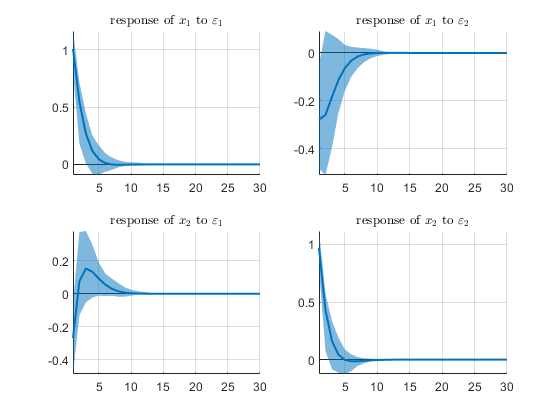

C0_hat*C0_hat'

Thus

B_hat = inv(C0_hat)

Sigma_hat =     1.0000   -0.2773
   -0.2773    1.0000


Gamma_0_hat = C0_hat\Est_Mdl_VAR.Constant % left dividing here is the faster and more accurate option that first taking the inverse
Gamma_1_hat = C0_hat\Est_Mdl_VAR.AR{1}

C0_hat =     1.0000         0
   -0.2773    0.9608


e_hat = infer(Est_Mdl_VAR,Y);
epsilon_hat_Chol = e_hat/C0_hat;

ans =     1.0000   -0.2773
   -0.2773    1.0000


To find the IRF, we will construct the vector moving average representation of the identified structural model

Create the lag operator:


$$(B-\Gamma_1L)\mathbf{y}_t=\Gamma_0 +\mathbf{\varepsilon}_t$$


Gamma_L=LagOp({B_hat,-Gamma_1_hat})

B_hat =     1.0000         0
    0.2886    1.0408


Invert it to find the vector moving average representation:


$$\mathbf{y}_t=(B-\Gamma_1L)^{-1}\Gamma_0 +(B-\Gamma_1L)^{-1}\mathbf{\varepsilon}_t = \mathbf{\mu}+\sum_{i=0}^\infty C_i \mathbf{\varepsilon}_t$$


C_LagOp = mldivide(Gamma_L,eye(num_variables),'Degree',irf_periods,'RelTol',0.0001) 

Gamma_0_hat =    -0.0085
   -0.0693


These coefficients are the IRFs. Note, that technically, there are an infinite number of them. In practice, however, because the VAR is stationary, the impact of shocks in the distant past fade out. This is equivalent to the coefficients in the VMA representation approaching zero. In this case, only a few coefficients needed to be computed before the coefficients (technically the matrix norm of the coefficient matrix) became closer to zero than than 'RelTol', a parameter we can control. 

C_L = NaN(C_LagOp.Dimension,C_LagOp.Dimension,C_LagOp.Degree+1);

Gamma_1_hat =     0.5087   -0.1210
    0.3655    0.4885


for i=1:C_LagOp.Degree+1 
    C_L(:,:,i) = C_LagOp.Coefficients{i-1};% mldivide stores in an unusual type, so we have to do this by hand
end
IRF_Chol = permute(C_L,[3,2,1]); % C_L is [n x n x irf periods], for the IRF plot function we need it as [irf_periods x n x n]

Notice how to top-right panel has changed - variable 1 now has a zero initial response to shock 2

irf_plot(IRF_Chol) 

Gamma_L =     2-D Lag Operator Polynomial:
    -----------------------------
        Coefficients: [Lag-Indexed Cell Array with 2 Non-Zero Coefficients]
                Lags: [0 1]
              Degree: 1
           Dimension: 2

## Blanchard Quah

Blanchard and Quah (1988) consider identification of temporary and permanent shocks. 


$$\mathbf{y}_t=A_0 +A_1\mathbf{y}_t+\mathbf{e}_t$$


They use two variables - output growth $\triangle Y
$ and the unemployment rate $u
$, where the *level* of output is assumed to have a unit root (i.e. a stochastic trend - accumulating permanent shocks over time.)

Consider VMA representation:


$$\left[\begin{array}{c}
\triangle Y_t\\
u_t\\
\end{array}\right]= \mathbf{\mu}+\sum_{i=0}^\infty F_i \left[\begin{array}{c}
\varepsilon^s_{t-i}\\
\varepsilon^d_{t-i}\\
\end{array}\right] = \mathbf{\mu}+F(L) \left[\begin{array}{c}
\varepsilon^s_{t}\\
\varepsilon^d_{t}\\
\end{array}\right] $$


"Demand shocks" $\varepsilon^d_{t}$ are presumed to have no long run impact on output. By that logic, all the long impacts of all demand shocks on growth must cancel out to zero. This is the same as imposing a zero restriction on the top righthand corner of $\sum_{i=0}^\infty F_i=F(1)$.

How do we achieve this? Again we use the fact that the coefficients eventually fade out, so we have a good representation of this infinite summation by using only a small number of terms. We also employ the Cholesky decomposition, but applied to a different part of the model.

Consider the VMA representation of the estimated reduced form:


$$\left[\begin{array}{c}
\triangle Y_t\\
u_t\\
\end{array}\right]= \mathbf{\mu}+\sum_{i=0}^\infty C_i \left[\begin{array}{c}
e_{1,t-i}\\
e_{2,t-i}\\
\end{array}\right]=\mathbf{\mu}+C(L) \mathbf{e}^{}_t$$


with $\Sigma=\mathbb{E}(\mathbf{e}^{}_t\mathbf{e}_t ^\prime )$ 

Let $S=chol(C(1)\Sigma C(1)')$, the lower triangular Cholesky factor of the quadratic form of the accumulated IRF with the covariance matrix as weights, and $K=C(1)^{-1}S$ then we have the identified shocks:


$$\left[\begin{array}{c}
\varepsilon^s_{t}\\
\varepsilon^d_{t}\\
\end{array}\right] = K^{-1}\left[\begin{array}{c}
e_{1,t}\\
e_{2,t}\\
\end{array}\right] $$


C_sum = sum(C_L,3) %C(1) (sum along third dimension)

C_LagOp =     2-D Lag Operator Polynomial:
    -----------------------------
        Coefficients: [Lag-Indexed Cell Array with 15 Non-Zero Coefficients]
                Lags: [0 ... 14]
              Degree: 14
           Dimension: 2

S = chol(C_sum*Sigma_hat*C_sum',"lower")
K = C_sum\S
epsilon_hat_BQ = e_hat/K;

And the impulse response function $F(L)=C(L)K$

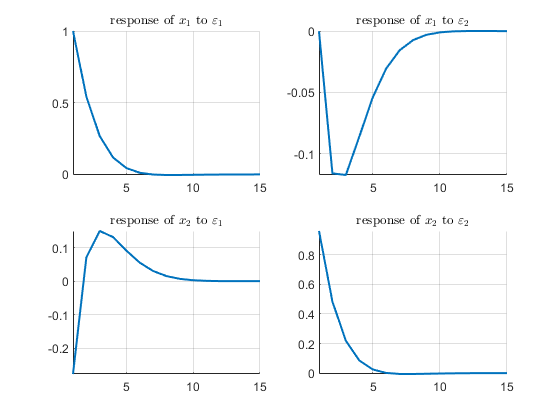

F_L = NaN(C_LagOp.Dimension,C_LagOp.Dimension,C_LagOp.Degree+1);
for t = 1:C_LagOp.Degree+1
    F_L(:,:,t)=C_L(:,:,t)*K;
end

% check BQ condition
F_sum = sum(F_L,3)

To illustrate that the procedure works, we compute the *cumulative *IRF - i.e. the cumulative/long-run impact of a shock over time. Notice how the top right panel is the only one that fades out to zero as we required. Why are the bottom panels also permanent? Unemployment is supposed to be stationary! Here, we are asking a different type of question. The bottom panels represent what would happen to employment if the shocks were permanent (non just an impulse), i.e. step functions equal to unity forever. 

CumIRF_BQ = permute(cumsum(F_L,3),[3,2,1]);

C_sum =     1.9680   -0.4311
    0.2742    1.7504


S =     2.1282         0
   -0.5345    1.6085


K =     0.9809    0.1946
   -0.4590    0.8885


F_sum =     2.1282    0.0000
   -0.5345    1.6085


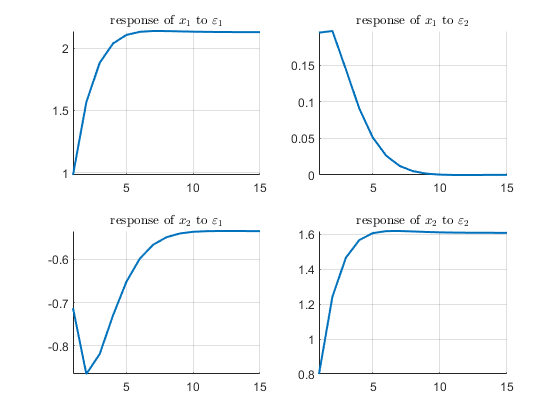

irf_plot(CumIRF_BQ)